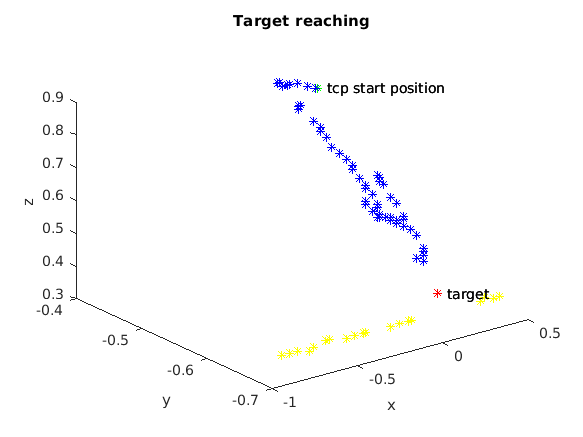

clear;

%% begin time of target reaching %%
timestamp = 234882000000;

load('time_error.mat');
load('error_class_data.mat');
load('pred_pos_data.mat');

start_i = 29;
time = time * 10^(-9);
time = time(start_i:size(time));
time = time - time(1);
error_nf = error_data(start_i:size(error_data, 1), 1);
error_ud = error_data(start_i:size(error_data, 1), 2);
error_lr = error_data(start_i:size(error_data, 1), 3);

start_i_error_class = 28;
error_class_data_time = error_class_data_time * 10^(-9);
error_class_data_time = error_class_data_time(start_i_error_class:size(error_class_data_time));
error_class_data_time = error_class_data_time - error_class_data_time(1);

tcp_x_i = 4; tcp_y_i = 5; tcp_z_i = 6;
tcp_data = error_class_data(start_i_error_class:size(error_class_data),tcp_x_i:tcp_z_i);
subject = error_class_data(start_i_error_class,1:3);
subject(2) = subject(2) + 0.12;


%%% TRAJECTORY %%%
%% comment hold on and hold off for 3d figure instead of 2d %%
x = tcp_data(1:size(tcp_data),1);
y = tcp_data(1:size(tcp_data),2);
z = tcp_data(1:size(tcp_data),3);
hold on
plot3(x(1),y(1),z(1),'*g');
plot3(x(2:size(x)),y(2:size(y)),z(2:size(z)),'*b');
plot3(subject(1),subject(2),subject(3),'*r');
pred_pos_n = size(pred_pos_data, 1);
plot3(pred_pos_data(1:pred_pos_n,1),pred_pos_data(1:pred_pos_n,2),pred_pos_data(1:pred_pos_n,3),'*y');
title('Target reaching')
xlabel('x')
ylabel('y')
zlabel('z')
text(x(1),y(1),z(1),"  tcp start position")
text(subject(1),subject(2),subject(3),"  target")
hold off

%%% TRAJECTORY %%%


%%% ERROR %%%
% hold on
% tiledlayout(3,1)
% ax1 = nexttile;
% p1 = plot(ax1,time,error_lr);
% set(p1,'LineWidth',3);
% title(ax1,'L/R')
% ax2 = nexttile;
% p2 = plot(ax2,time,error_ud);
% set(p2,'LineWidth',3);
% title(ax2,'U/D')
% ax3 = nexttile;
% p3 = plot(ax3,time,error_nf);
% set(p3,'LineWidth',3);
% title(ax3,'N/F')
% xlabel('Time (seconds)')
% hold off
%%% ERROR %%%
